**2. (10 marks) In this exercise, we will apply AR modeling to speech samples. Download “m01ae.wav”,  “w01ae.wav”, “w01ih.wav”, and “w01uw.wav” from “Course Content -> Week 4” under the “Asynchronous”  section. Complete the following: **

**a. For each speech sample, plot the estimated variance of the white noise input against the model order,  with the model order ranging from 1 to 25. See the documentation for “aryule” command for  accessing the estimated variance. Comment on the results. What would be a good model order for  modelling these waveforms?**

Read audios

[A1,Fs1] = audioread('m01ae.wav');
[A2,Fs2] = audioread('w01ae.wav');
[A3,Fs3] = audioread('w01ih.wav');
[A4,Fs4] = audioread('w01uw.wav');
Model_Orders = 1:25; % Model orders ranging from 1 to 25
variances = zeros(length(Model_Orders), 4);

Estimate variance of each white noise input.

for order = Model_Orders
    % speech sample #1
    [~, varEst,~] = aryule(A1, order);
    variances(order, 1) = varEst;
    
    % speech sample #2
    [~, varEst,~] = aryule(A2, order);
    variances(order, 2) = varEst;
    
    % speech sample #3
    [~, varEst,~] = aryule(A3, order);
    variances(order, 3) = varEst;
    
    % speech sample #4
    [~, varEst,~] = aryule(A4, order);
    variances(order, 4) = varEst;
end

Plot variance of each white noise input against the model order. 

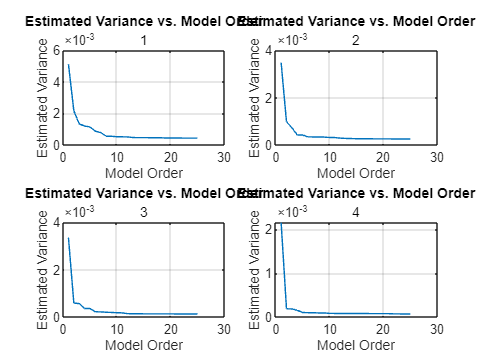

% Plot the results for each audio sample
figure;
for i = 1:4
    subplot(2, 2, i);
    plot(Model_Orders, variances(:, i));
    title('Estimated Variance vs. Model Order', i);
    xlabel('Model Order');
    ylabel('Estimated Variance');
    grid on;
end

**b. For each speech sample and the chosen model order, compute and plot the periodogram and AR spectral estimates. See “LinearPredictionExample.mlx” for guidance. Comment on the results. In  particular, what is the AR spectral estimate trying to model? Are the AR spectral estimates the same across the four speech samples? **

Find AR Model from Signal using the Yule-Walker Method for each speech sample

[d1,p1] = aryule(A1,13);
[d2,p2] = aryule(A2,12);
[d3,p3] = aryule(A3,12);
[d4,p4] = aryule(A4,10);

Compare AR Model with AR Signal

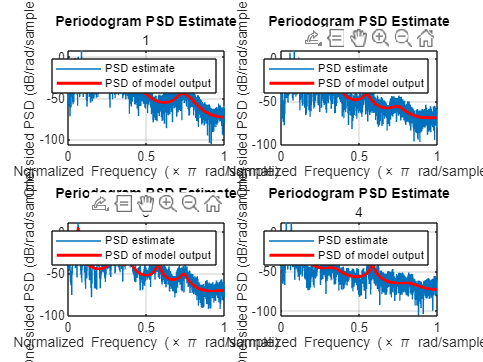

[H1,w1] = freqz(sqrt(p1),d1); %compute the output power spectral density of model 1
[H2,w2] = freqz(sqrt(p2),d2); %compute the output power spectral density of model 2
[H3,w3] = freqz(sqrt(p3),d3); %compute the output power spectral density of model 3
[H4,w4] = freqz(sqrt(p4),d4); %compute the output power spectral density of model 4

% Plot the periodogram for each signal and overlay the AR spectral estimate
figure;
model = {A1, A2, A3, A4};
Hs = {H1, H2, H3, H4};
ws = {w1, w2, w3, w4};
for i = 1:4
    subplot(2, 2, i);
    periodogram(model{i}); % Plot periodogram of signal
    hold on; 
    hp = plot(ws{i}/pi, 20*log10(2*abs(Hs{i})/(2*pi)), 'r'); % Scale to make one-sided PSD
    hp.LineWidth = 2;
    title('Periodogram PSD Estimate', i);
    xlabel('Normalized Frequency (\times \pi rad/sample)');
    ylabel('One-sided PSD (dB/rad/sample)');
    legend('PSD estimate','PSD of model output');
end